## Q2. (A)

Given System,

Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
P = Gv*Gv1*Gv2*Gv3*Gv4;

Initialize transfer funciton

s = tf('s');

M = 10^(6/20);
A = 1000;  
BW = 3000*2*pi; 

Initialize weights of 1st and 2nd order.

Wp_1 = (s/M+BW)/(s+BW/A);
Wp_2 = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;

Generate the controller using mixsym for first order. Also, computed the Loop shape, Sensitivity, and the complementary sensitivity functions.

[K_1,CL,GAM_1,info] = mixsyn(P,Wp_1,[],[]); 

L1 = P*K_1;
S1 = 1/(1+L1);
T1 = 1-S1;

Sensitivity funciton plot

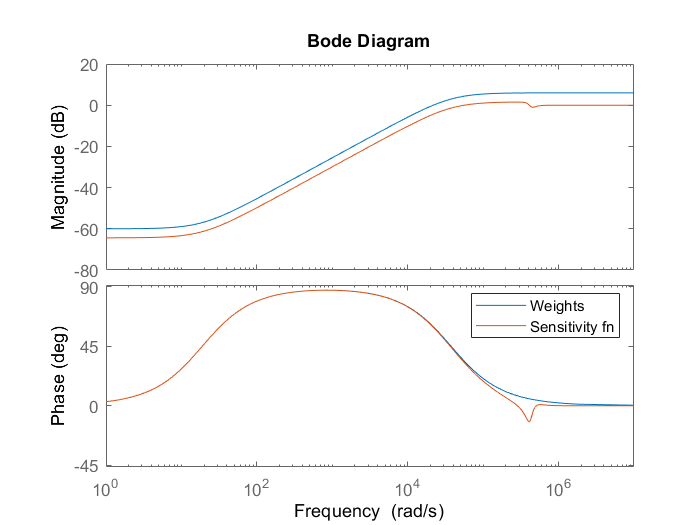

figure
bode(1/Wp_1,S1)
legend('Weights','Sensitivity fn',"Location","best")

Step response of the closed loop system (1st order)

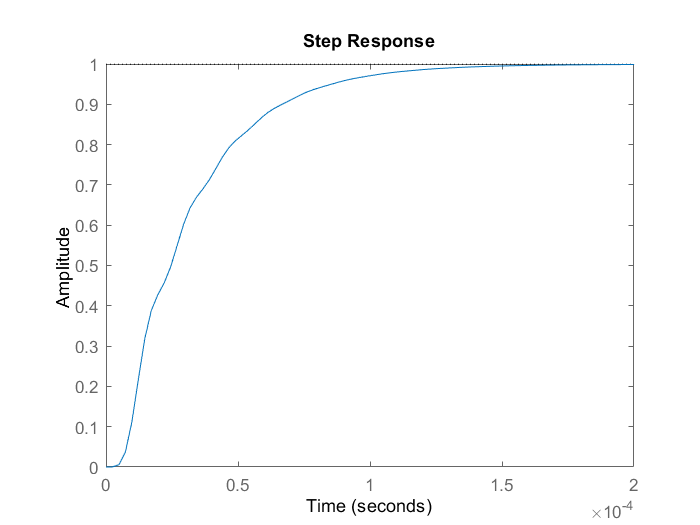

figure
step(T1)

Generate the controller using mixsym for second order. Also, computed the Loop shape, Sensitivity, and the complementary sensitivity functions.

[K_2,CL,GAM_2,info] = mixsyn(P,Wp_2,[],[]);  %This is the magic synthesis command.  Much of this class is about how and why this works.  NOTE:  For comparison to loopsyn below, be sure to use [],[] for 2nd two arguments.
L = P*K_2;
S = 1/(1+L);
T = 1-S;

Sensitivity plot

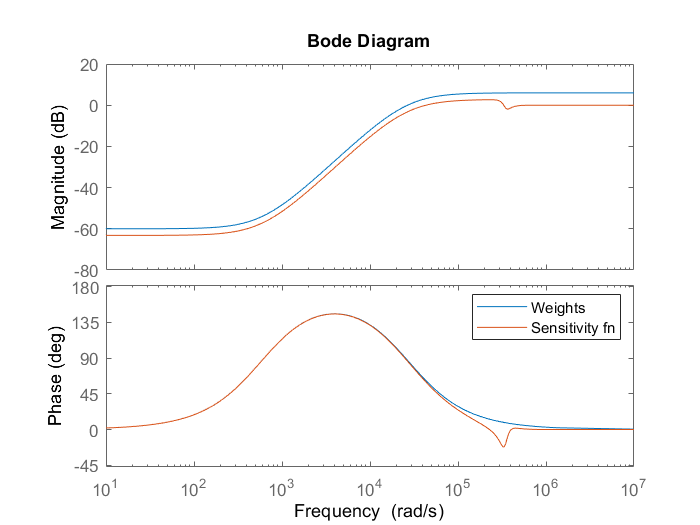

figure
bode(1/Wp_2,S)
legend('Weights','Sensitivity fn')

Step response of the closed loop system (2nd order)

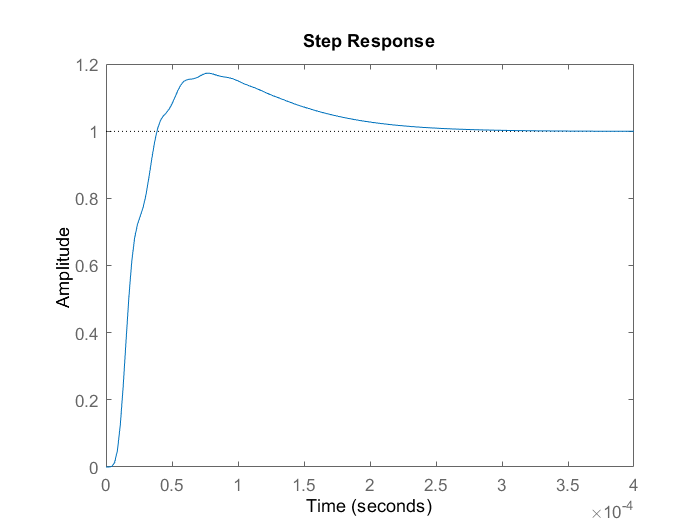

figure
step(T)

Check the limit of bandwidth for second order weights

GAM_wp2 = 0.5;
while GAM_wp2 < 1
    Wp_wp2 = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
    [K_2,CL,GAM_wp2,info] = mixsyn(P,Wp_wp2,[],[]);
    BW = BW + 50;
end
BW

BW = 3.9050e+04

As we can see that we have a threshold for bandwidth above which mixsyn does not produce a controller which has Gamma <1. Therefore, there exists a limit to sensitivity crossing frequency.

## Q2. (B)

Initialize the weight parameters

At = 80;
Mt = 40;
BW = 10000*2*pi;
Wt = makeweight(1/At,BW,Mt);

Generate controller using mixsyn. Also, computed the Loop shape, Sensitivity, and the complementary sensitivity functions.

[K_t,CL,GAM_t,info] = mixsyn(P,Wp_2,[],Wt);
L_t = P*K_t;
S_t = 1/(1+L_t);
T_t = 1-S_t;

Gamma Value

GAM_t

GAM_t = 0.9679

Complementary Sensitivity function

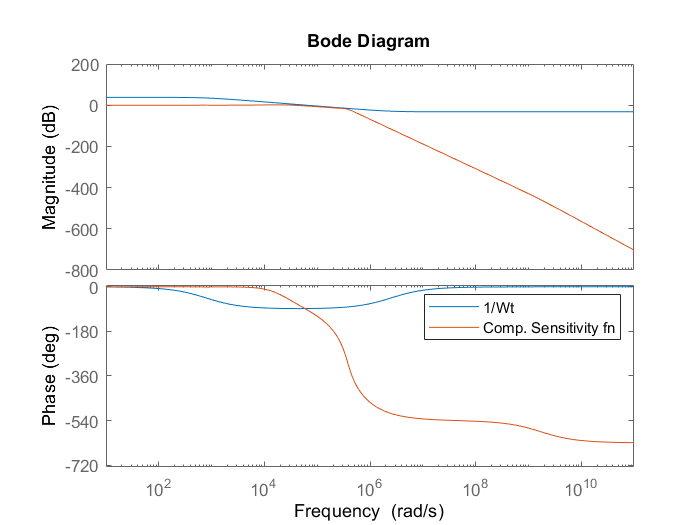

bode(1/Wt,T_t)
legend('1/Wt','Comp. Sensitivity fn')

Sensitivity function

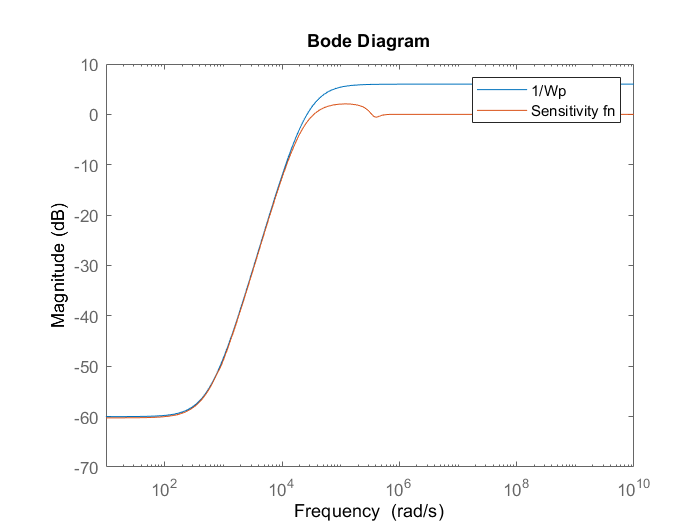

bodemag(1/Wp_2,S_t);
legend('1/Wp','Sensitivity fn')

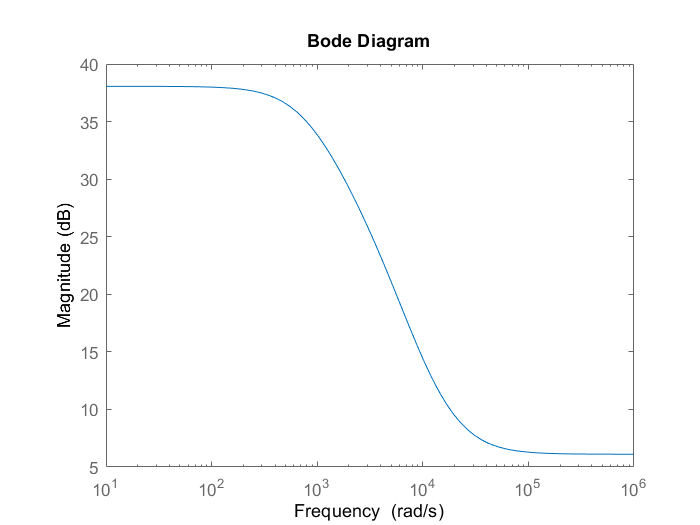

bodemag(1/Wt + 1/Wp)

We can see that 1/Wt + 1/Wp > 1. The constraint holds true.

## Q2. (C)

Initialize system parameters


s = tf('s');
Wu = 1/100;
GAM = 10;  
BW = 3000*2*pi; 
BW_step = 25;

Create loop to achieve the desired Gamma value.

while GAM>1
    Wp = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
    Wt = makeweight(0.5,5*BW,1000);
    [K_u,CL,GAM,info] = mixsyn(P,Wp,Wu,Wt); 
    BW = BW - BW_step; 
end

Gamma Value

GAM

GAM = 0.9919

Generate controller using mixsyn. Also, computed the Loop shape, Sensitivity, and the complementary sensitivity functions.

L_u = P*K_u;
S_u = 1/(1+L_u);
T_u = 1-S_u;

Complementary Sensitivity Plot

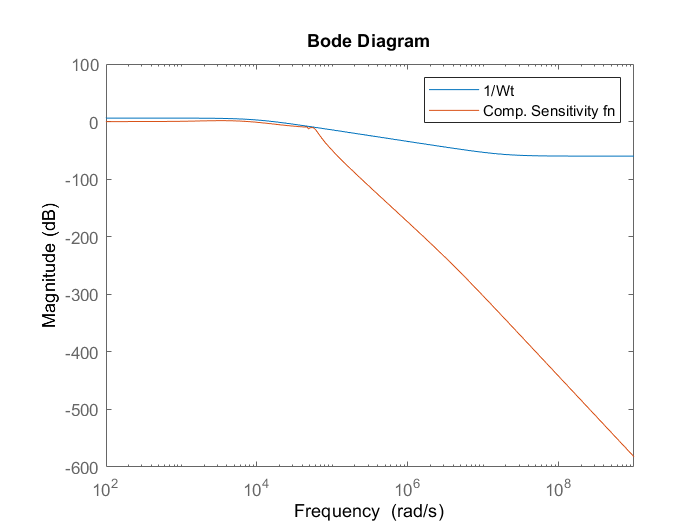

bodemag(1/Wt,T_u)
legend('1/Wt','Comp. Sensitivity fn')

Sensitivity Plot

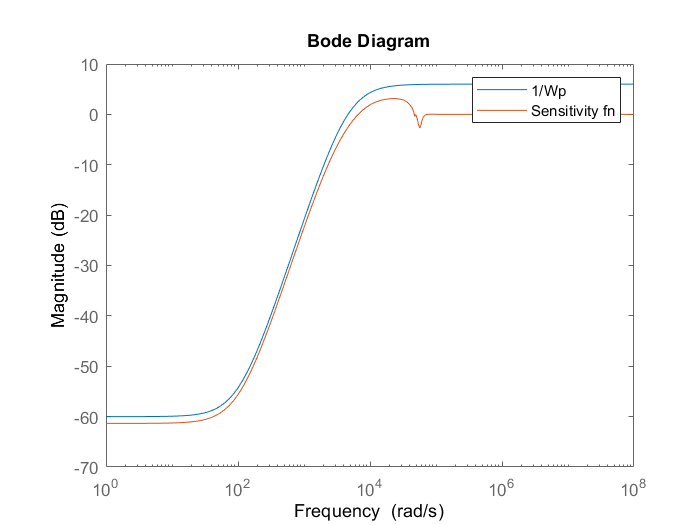

bodemag(1/Wp,S_u);
legend('1/Wp','Sensitivity fn')

Controller weight plot

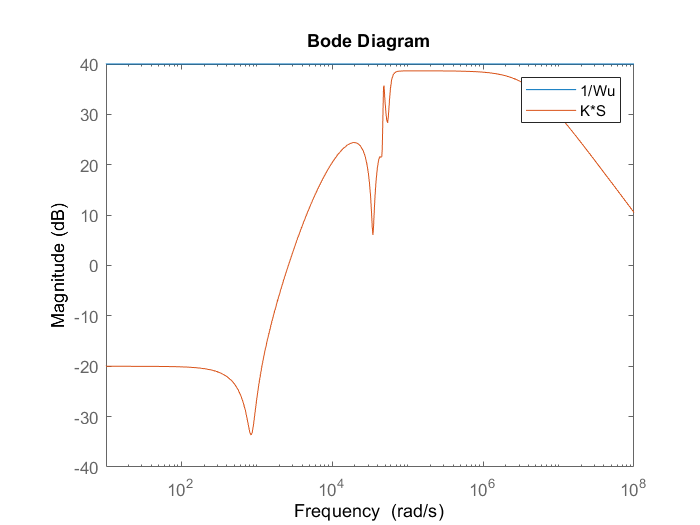

bodemag(tf(1/Wu,1), K_u*S_u)
legend('1/Wu','K*S')

norm(CL,'inf')

ans = 0.9919